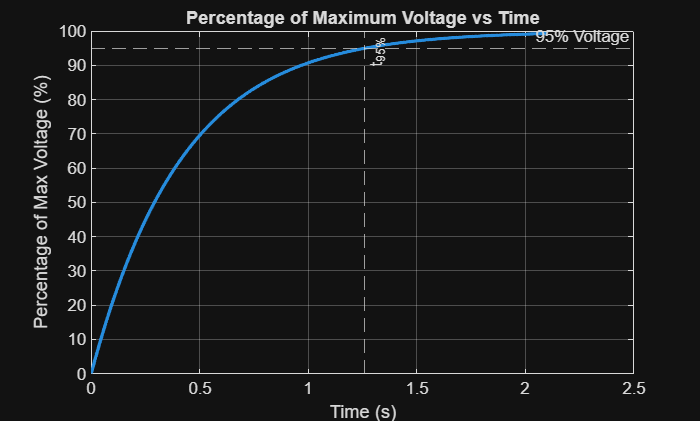

clear; clc; close all;

%% ---------------- PARAMETERS ----------------
V_pack = 117.6;          % Accumulator voltage (V)
C_dc   = 4200e-6;        % DC-link capacitance (F)
R      = 100;           % Precharge resistor (Ohms)

%% ---------------- TIME VECTOR ----------------
tau = R * C_dc;
t = linspace(0, 5*tau, 1000);

%% ---------------- EQUATIONS ----------------

% Voltage (Charging)
% V(t) = V_pack * (1 - exp(-t/RC))
V = V_pack * (1 - exp(-t/(R*C_dc)));

% Percentage Voltage
V_percent = (V / V_pack) * 100;

% Current
% I(t) = (V/R) * exp(-t/RC)
I = (V_pack / R) * exp(-t/(R*C_dc));

% Power Dissipation
% P(t) = I^2 * R
P = I.^2 * R;

%% ---------------- KEY POINTS ----------------
V_95 = 0.95 * V_pack;
t_95 = -tau * log(1 - 0.95);

P_peak = max(P);
P_avg = (0.5 * C_dc * V_pack^2) / t_95;

%% ---------------- PLOTS ----------------

% 1. Percentage Voltage vs Time
figure('Name','Percentage Voltage');
plot(t, V_percent, 'LineWidth', 2); hold on;
yline(95,'--','95% Voltage');
xline(t_95,'--','t_{95%}');
xlabel('Time (s)');
ylabel('Percentage of Max Voltage (%)');
title('Percentage of Maximum Voltage vs Time');
grid on;

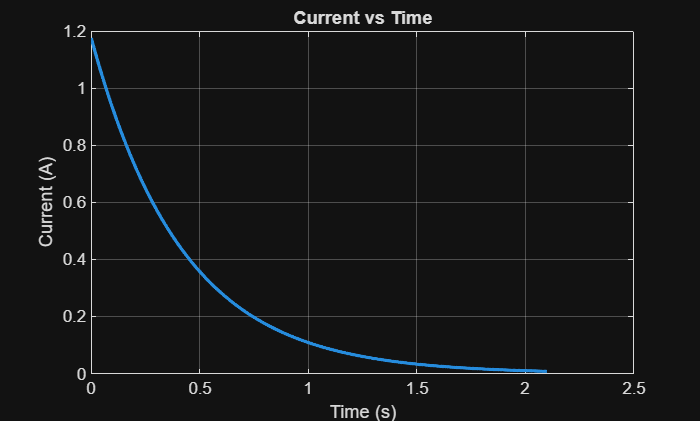


% 2. Current vs Time
figure('Name','Current');
plot(t, I, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Current (A)');
title('Current vs Time');
grid on;

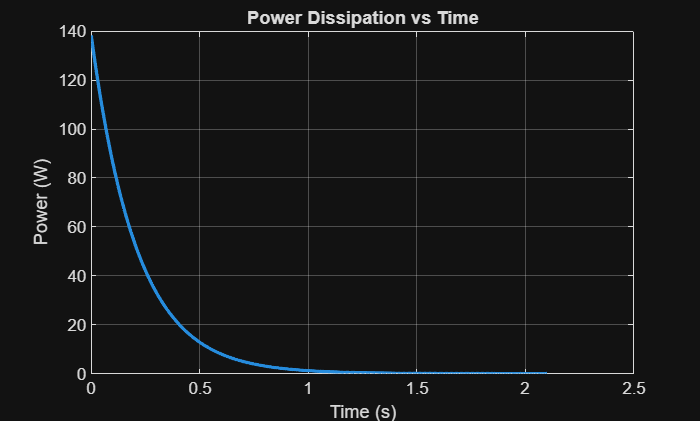


% 3. Power vs Time
figure('Name','Power Dissipation');
plot(t, P, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Power (W)');
title('Power Dissipation vs Time');
grid on;


%% ---------------- OUTPUT ----------------
fprintf('--- RESULTS ---\n');

--- RESULTS ---


fprintf('Time Constant (tau): %.3f s\n', tau);

Time Constant (tau): 0.420 s


fprintf('Time to 95%% Voltage: %.3f s\n', t_95);

Time to 95% Voltage: 1.258 s


fprintf('Peak Power: %.2f W\n', P_peak);

Peak Power: 138.30 W


fprintf('Average Power: %.2f W\n', P_avg);

Average Power: 23.08 W
